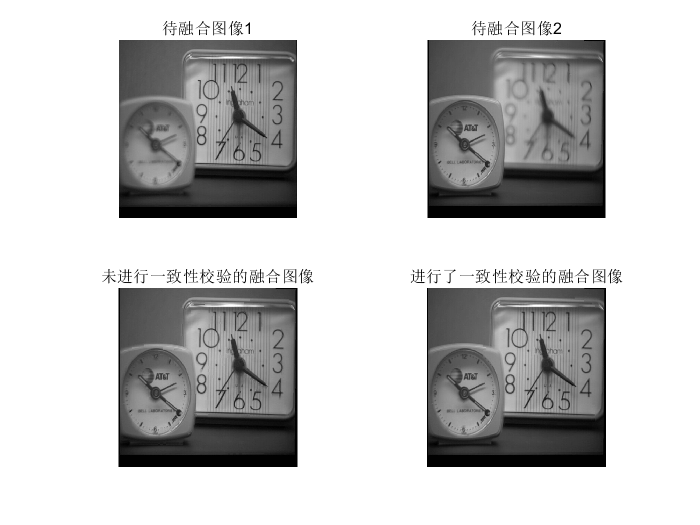

close all; clear; clc;
im1 = imread("clock1.jpg");
im2 = imread("clock2.jpg");
if size(im1,3) == 3
    im1 = rgb2gray(im1);
end
if size(im2,3) == 3
    im2 = rgb2gray(im2);
end
[fusedDctVar,fusedDctVarCv] = DctFusion(im1,im2);
figure;
subplot(2,2,1), imshow(im1), title('待融合图像1');
subplot(2,2,2), imshow(im2), title('待融合图像2');
subplot(2,2,3), imshow(fusedDctVar,[]), title('未进行一致性校验的融合图像');
subplot(2,2,4), imshow(fusedDctVarCv,[]), title('进行了一致性校验的融合图像');

imwrite(uint8(fusedDctVarCv),'DCT融合后图像.jpg');